# Homework 2

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1 (Leap Year Exercise)

 A year is a leap year if it is a multiple of 4, except for years divisible by 100 but not by 400. In simpler terms, a non-century year is a leap year if it is divisible by 4; a century year is a leap year if it is divisible by 40

### Part (a) Write a script which determines whether a given year is a leap year or not

type Homework_2_Problem_1.m

%inputYear = input('Enter a year:');
if (mod(inputYear, 100) == 0)
    if (mod(inputYear, 400) == 0)
    disp(['The year ', num2str(inputYear),' is a century year that is a leap year']);
    else
    disp(['The year ', num2str(inputYear),' is not a leap year']);
    end
elseif (mod(inputYear, 4) == 0)
disp(['The year ', num2str(inputYear),' is not a century year, but it is a leap year']);
else 
disp(['The year ', num2str(inputYear),' entered is not a leap year']);
end


### Part (b) Run your script with the years in the example above.

inputYear = 2020;
run Homework_2_Problem_1.m

The year 2020 is not a century year, but it is a leap year


inputYear = 1900;
run Homework_2_Problem_1.m

The year 1900 is not a leap year


inputYear = 2000;
run Homework_2_Problem_1.m

The year 2000 is a century year that is a leap year


## Problem 2 (3D Coordinate Conversion)

### Part (a) (Written Portion)

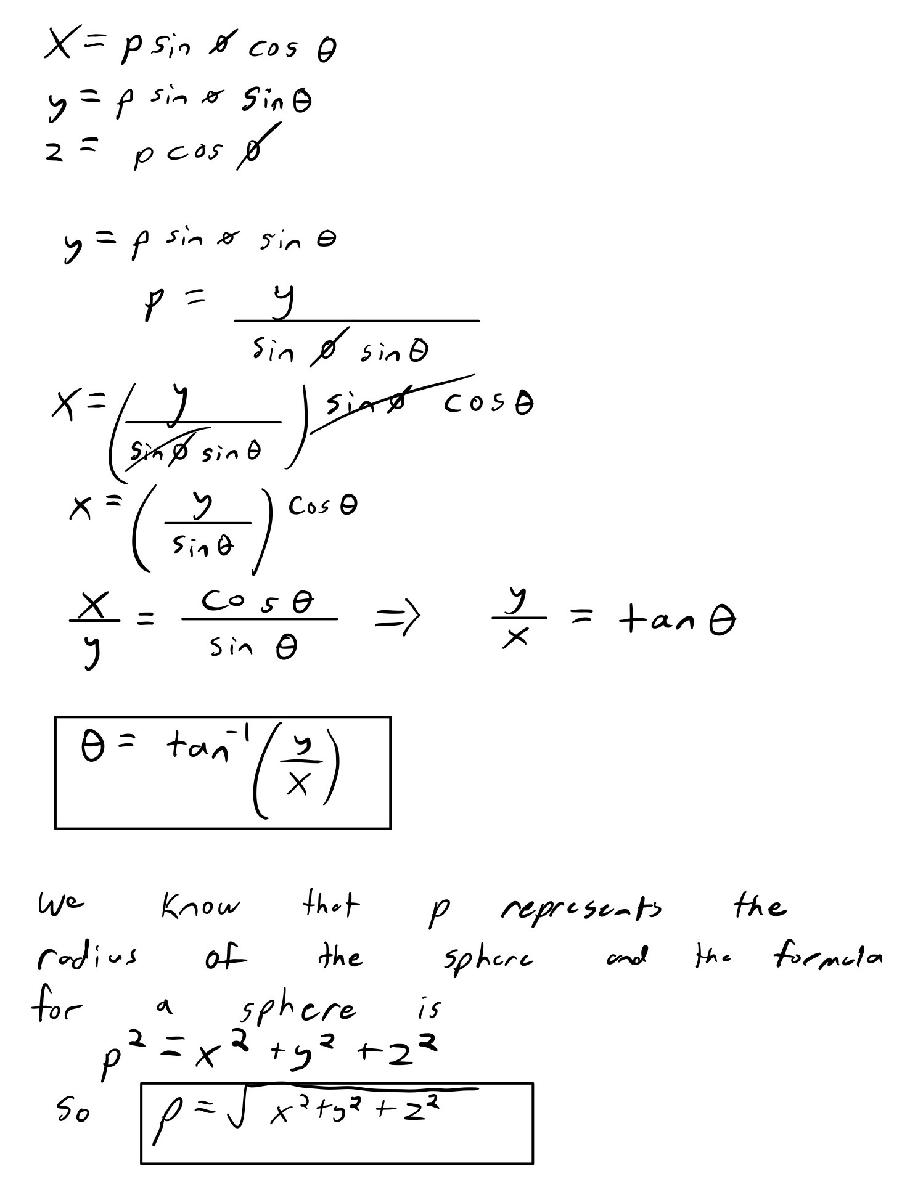

### 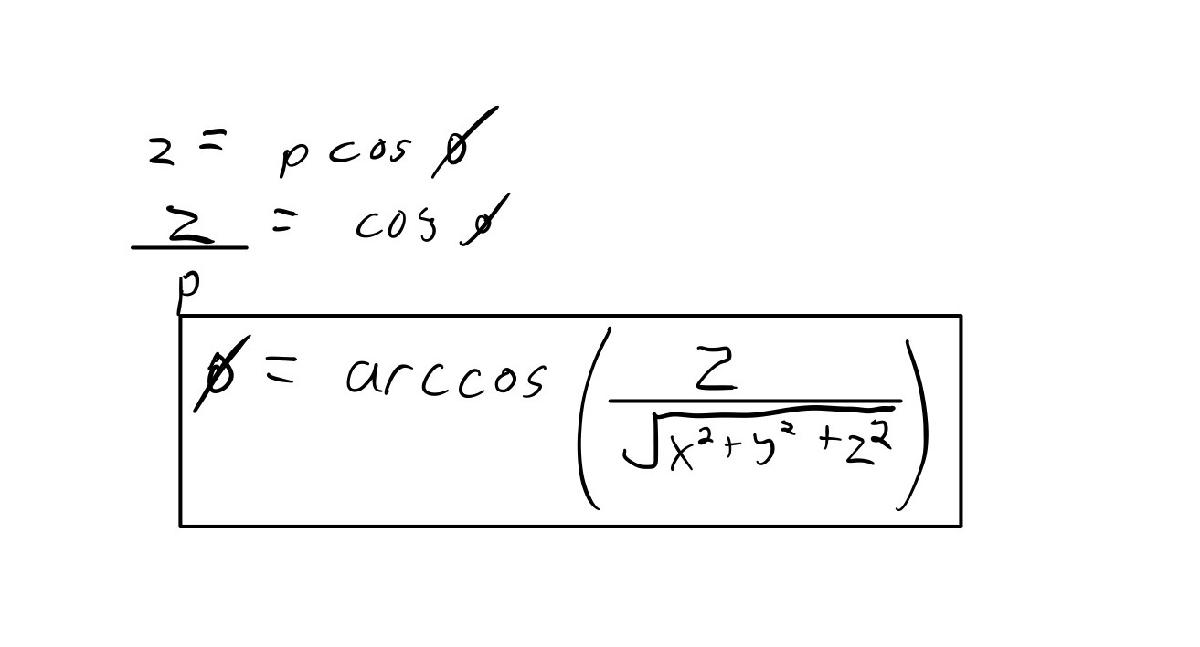

### Part (b) (Coding Portion)

type Homework_2_Problem_2.m

%x = input('Enter the x - coordinate: ');
%y = input('Enter the y - coordinate: ');
%z = input('Enter the z - coordinate: ');
format long g;
rho = sqrt((x^2)+(y^2)+(z^2));
phi = acos(z / (sqrt((x^2)+(y^2)+(z^2))));
theta = atan2(y,x);
fprintf('The inputted cartesian coordinates are (%d, %d, %d)\n', x,y,z);
fprintf('In spherical coordinates (rho, phi, theta) are \n(%12.12f, %12.12f, %12.12f)\n', rho, phi, theta)


### Part (c) Test Points 

1.) (x, y, z) = (1, 2, -2)

2.) (x, y, z) = (0, -3, 4)

3.) (x, y, z) =  (-5, -12, 1)

4.) (x, y, z) = (0, 0, -7)

x = 1;
y = 2;
z = -2;
run Homework_2_Problem_2.m

The inputted cartesian coordinates are (1, 2, -2)
In spherical coordinates (rho, phi, theta) are 
(3.000000000000, 2.300523983022, 1.107148717794)


x = 0;
y = -3;
z = 4;
run Homework_2_Problem_2.m

The inputted cartesian coordinates are (0, -3, 4)
In spherical coordinates (rho, phi, theta) are 
(5.000000000000, 0.643501108793, -1.570796326795)


x = -5;
y = -12;
z = 1;
run Homework_2_Problem_2.m

The inputted cartesian coordinates are (-5, -12, 1)
In spherical coordinates (rho, phi, theta) are 
(13.038404810405, 1.494024435525, -1.965587446495)


x = 0;
y = 0;
z = -7;
run Homework_2_Problem_2.m

The inputted cartesian coordinates are (0, 0, -7)
In spherical coordinates (rho, phi, theta) are 
(7.000000000000, 3.141592653590, 0.000000000000)


## Problem 3 (Game of 3-stick)

In this game of three stick we are going to use the rand() function which will produce lengths between 0 and 1. From there we will use the triangle inequality theorem which states that the sum of the two side lengths of a triangle is always greater than the third side and if it is not the case for all three possible combinations of side lengths then it is not a triangle. So we will use this to find out if the random three lengths will make a triangle or not.

numOfGames = 0;
numOfWins = 0;
numOfLosses = 0;
for k = 1:1000000
    a = rand();
    b = rand();
    c = rand();
    if (a + b > c) && (a + c > b) && (b + c > a)
        numOfWins = numOfWins + 1;
    else 
        numOfLosses = numOfLosses + 1;
    end
    numOfGames = numOfGames + 1;
end
fprintf('The Number of Games is %d\n', numOfGames);

The Number of Games is 1000000


fprintf('The Number of Wins is %d\n', numOfWins);

The Number of Wins is 500620


fprintf('The Number of Losses is %d\n', numOfLosses);

The Number of Losses is 499380


fprintf('The Probability of Winning a game is %12.12f\n', numOfWins / numOfGames)

The Probability of Winning a game is 0.500620000000


## Problem 4 (Gap of 10)

Biased Coin Toss with Tails being 3 times more likely. So this can be done by using the rand() function and having 3/4 of the numbers in rand() to be tails while the rest goes to heads.

for k = 1:10
tailWin = 0;
headWin = 0;
totalTosses = 0;
    while (abs(tailWin - headWin) < 10)
    coinFlip = rand();
        if coinFlip <= 3/4
            tailWin = tailWin + 1;
        else 
            headWin = headWin + 1;
        end
    totalTosses = totalTosses + 1;
    end
disp(['Simulation ', num2str(k), ' done in ', num2str(totalTosses), ' tosses.']);
end

Simulation 1 done in 16 tosses.
Simulation 2 done in 18 tosses.
Simulation 3 done in 28 tosses.
Simulation 4 done in 14 tosses.
Simulation 5 done in 12 tosses.
Simulation 6 done in 22 tosses.
Simulation 7 done in 22 tosses.
Simulation 8 done in 18 tosses.
Simulation 9 done in 10 tosses.
Simulation 10 done in 10 tosses.


## Problem 5 (Sequences Converging to PI)

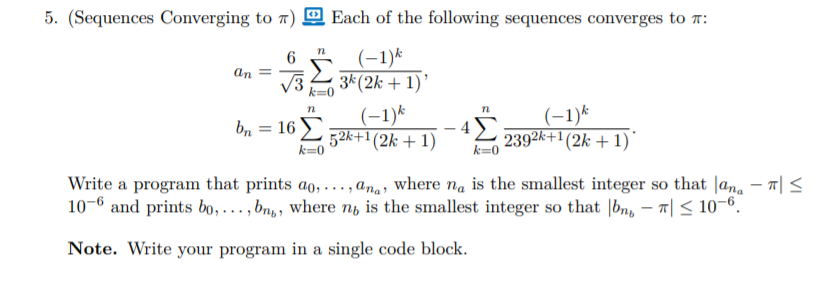

errTol = 10e-6;
err = inf;
n = 0;

while err > errTol
aSum = 0;
    for k = 0:n
        aSum = aSum + (((-1)^k)/((3^k * (2 * k + 1))));
    end
overallSum = (6/sqrt(3)) * aSum;
err = abs(overallSum - pi);
fprintf('a_%d = %12.12f and the error is %12.12f\n', k, overallSum, err);
n = n + 1;
end

a_0 = 3.464101615138 and the error is 0.322508961548
a_1 = 3.079201435678 and the error is 0.062391217912
a_2 = 3.156181471570 and the error is 0.014588817980
a_3 = 3.137852891596 and the error is 0.003739761994
a_4 = 3.142604745663 and the error is 0.001012092073
a_5 = 3.141308785463 and the error is 0.000283868127
a_6 = 3.141674312699 and the error is 0.000081659109
a_7 = 3.141568715942 and the error is 0.000023937648
a_8 = 3.141599773812 and the error is 0.000007120222



errTol = 10e-6;
err = inf;
n = 0;

while err > errTol
bSumLeft = 0;
bSumRight = 0;
    for k = 0:n
        bSumLeft = bSumLeft + (((-1)^k) / (5^(2*k+1) * (2*k+1)));
        bSumRight = bSumRight + (((-1)^k) / (239^(2*k+1) * (2*k+1)));
    end
overallSum = (16 * bSumLeft) - (4 * bSumRight);
err = abs(overallSum - pi);
fprintf('b_%d = %12.12f and the error is %12.12f\n', k, overallSum, err);
n = n + 1;
end

b_0 = 3.183263598326 and the error is 0.041670944737
b_1 = 3.140597029326 and the error is 0.000995624264
b_2 = 3.141621029325 and the error is 0.000028375735
b_3 = 3.141591772182 and the error is 0.000000881408
